# Create Scalograms Images

clear all;
close all;
clc;

## Setting Variables

audios_path = 'D:\UDENAR\Electronic Engineering\Trabajo de Grado\Results\Teager\v2.0\Segmented heart sounds\Audios';
scalograms_path = 'D:\UDENAR\Electronic Engineering\Trabajo de Grado\Results\Teager\v2.0\Scalograms';
audio_filePattern = fullfile(audios_path, '*.wav');

## Read Audios

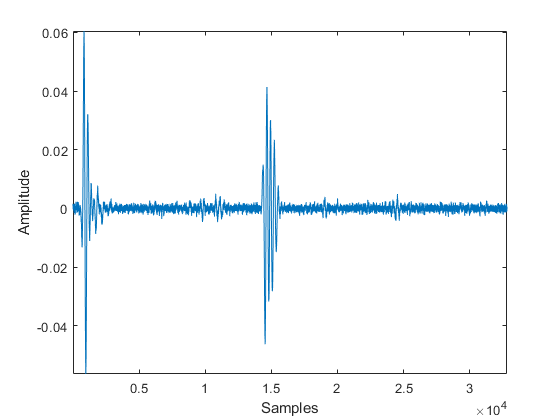

audio_files = dir(audio_filePattern);
audio_filename = audio_files(7).name;
label = audio_filename(1);
[y, fs] = audioread(strcat(audios_path, '\', audio_filename));
plot(y); xlabel('Samples'); ylabel('Amplitude'); axis tight;

## Create scalograms

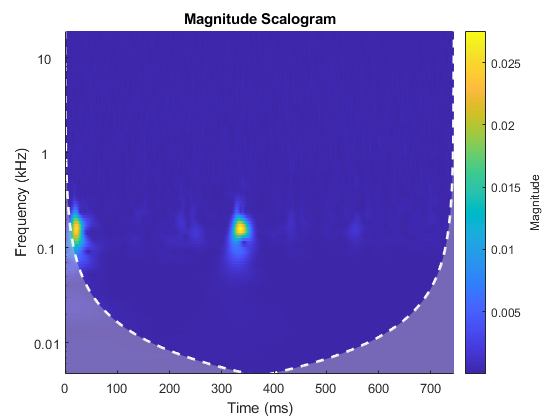

% Matlab function
figure;
cwt(y, fs);

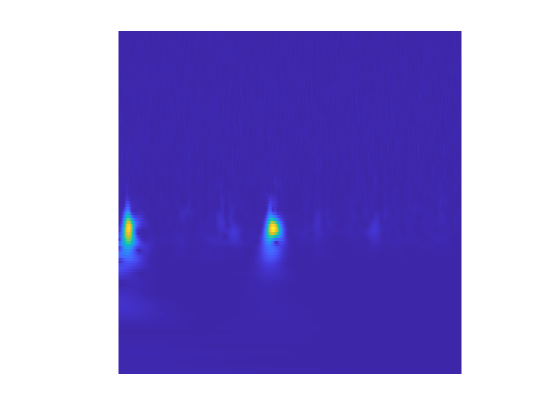

%
t = 0:1/fs:(length(y)-1)/fs;
[cfs, f] = cwt(y, fs);
figure1 = figure('WindowState','maximized','NumberTitle','off',...
    'Name','Figure', 'Resize', "on", 'Units', "pixels");
axes1 = axes('Parent', figure1);
hold(axes1, 'on');
image(t, f, abs(cfs), 'CDataMapping', 'scaled');
axis square;
set(axes1, 'XTick', []);
set(axes1, 'YTick', []);
set(axes1, 'Box', 'off');
set(axes1, 'Visible', 'off');
axis tight;
set(axes1, 'Yscale', 'log');
if strcmp(label, '-1')
    filePattern = fullfile(scalograms_path, '\Normal', ...
        strcat(audio_filename(1:end-4), '.jpg'));
else
    filePattern = fullfile(scalograms_path, '\Abnormal', ...
        strcat(audio_filename(1:end-4), '.jpg'));
end
exportgraphics(figure1, filePattern, 'Resolution', 64, 'BackgroundColor', [0.25, 0.15, 1]);